# 纯延时系统的控制器设计

系统由于状态响应，必然存在延时，一般情况下由于状态响应引入的延时可以通过状态反馈进行校正。若被控对象中存在纯延时$\tau$，其由传递函数$\mathrm{e}^{-\tau s}$描述，由于其不同于有限多项式的传递函数，因而难以对极点进行配置。下面我们以经典传递函数的方式讨论一种可用于含有纯延时系统的控制器设计。

假设被控对象除了动态响应$G(s)$外还有纯延时$\tau$，即传递函数为$G(s)\mathrm{e}^{-\tau s}$，设控制器传递函数为$D'(s)$。

则闭环传递函数为：$\mathcal{T}=\frac{D'(s)G(s)\mathrm{e}^{-\tau s}}{1+D'(s)G(s)\mathrm{e}^{-\tau s}}$

我们无法避免延时，将被控对象的延时作用到整个系统，让系统与没有延时的系统相比仅在输出存在延时。

这种情况下，闭环传递函数应当为$\mathcal{T}=\frac{D(s)G(s)}{1+D(s)G(s)}\mathrm{e}^{-\tau s}$，其中$D(s)$按无延时的被控对象$G(s)
$进行设计。

令两个传递函数相等，解得$D'(s)=\frac{D(s)}{1+D(s)G(s)(1-\mathrm{e}^{-\tau s})}$。

这就说明，我们只需要按照无延时的系统进行控制器设计，再在此基础上对控制器进行修正即可。

仿真结果如下图所示：可见以这种方法设计的系统确实表现为没有延时的系统进行了整体延时。

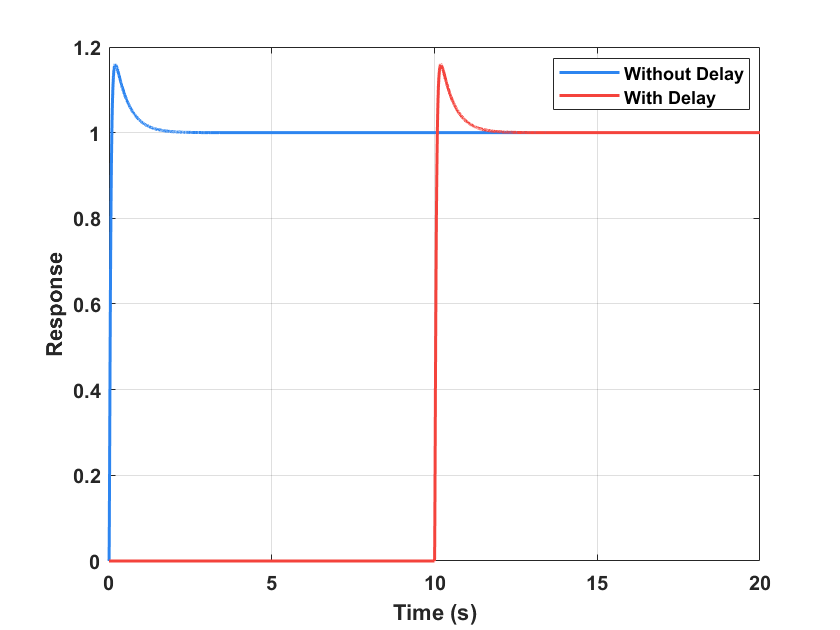

set(groot,'DefaultLineLineWidth',1.5)
set(groot,'DefaultAxesFontSize',10)
set(groot,'DefaultFigureColor','w')
set(groot,'DefaultAxesFontWeight','bold')
close all
clear;clc

T = 20;
Ts = 1e-3;
stepT = 0;

% Plant
s = tf('s');
omgn = 2;
Gs = 1/(s^2-omgn^2);
Td = 10;     % delay time

% PID Controller
P = 85;
I = 85;
D = 21;
N = 110;

sim('model5_DelayControl.slx')

figure
plot(t,y1)
hold on
grid on
plot(t,y2)
legend('Without Delay','With Delay','Location','best')
xlabel('Time (s)')
ylabel('Response')

应当注意的是，由于这种设计方法在控制器中使用了被控对象的传递函数，被控对象的理论参数与实际参数之间的误差将会引起系统的误差。实际上，这种设计对误差非常敏感，模型的不确定性甚至可能导致系统不稳定。